setup() ;
%setup('useGpu', true); % Uncomment to initialise with a GPU support

## Part 3.1: Prepare the data

% Load a database of blurred images to train from
imdb = load('data/text_imdb.mat') ;

Visualize the first image in the database

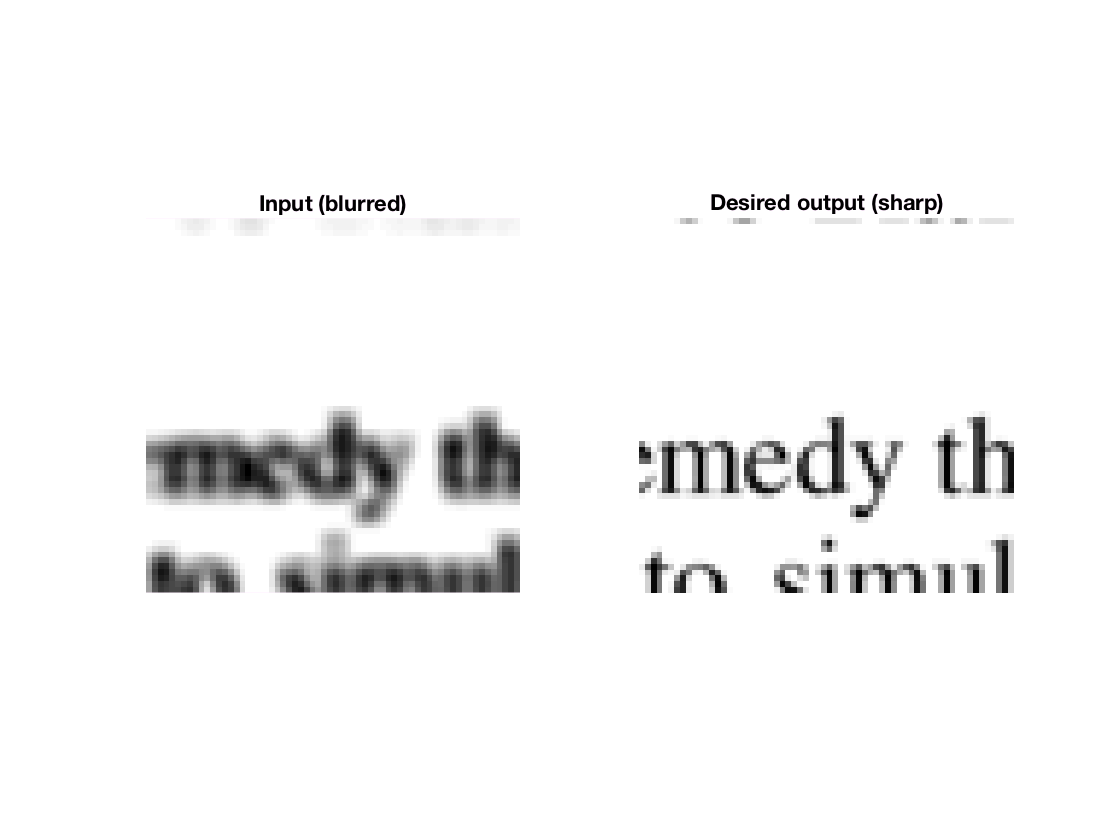

figure(31) ; set(gcf, 'name', 'Part 3.1: Data') ; clf ;

subplot(1,2,1) ; imagesc(imdb.images.data(:,:,:,1)) ;
axis off image ; title('Input (blurred)') ;


subplot(1,2,2) ; imagesc(imdb.images.label(:,:,:,1)) ;
axis off image ; title('Desired output (sharp)') ;

colormap gray ;

## Part 3.2: Create a network architecture

The expected input size (a single 64 x 64 x 1 image patch). This is used for visualization purposes.

net = initializeSmallCNN() ;
% net = initializeLargeCNN() ;

% Display network
vl_simplenn_display(net) ;

     layer|    0|    1|    2|    3|    4|         5|
      type|input| conv| relu| conv| relu|      conv|
      name|  n/a|conv1|relu1|conv2|relu2|prediction|
----------|-----|-----|-----|-----|-----|----------|
   support|  n/a|    3|    1|    3|    1|         3|
  filt dim|  n/a|    1|  n/a|   32|  n/a|        32|
 num filts|  n/a|   32|  n/a|   32|  n/a|         1|
    stride|  n/a|    1|    1|    1|    1|         1|
       pad|  n/a|    1|    0|    1|    0|         1|
----------|-----|-----|-----|-----|-----|----------|
   rf size|  n/a|    3|    3|    5|    5|         7|
 rf offset|  n/a|    1|    1|    1|    1|         1|
 rf stride|  n/a|    1|    1|    1|    1|         1|
----------|-----|-----|-----|-----|-----|----------|
 data size|   64|   64|   64|   64|   64|        64|
data depth|    1|   32|   32|   32|   32|         1|
  data num|    1|    1|    1|    1|    1|         1|
----------|-----|-----|-----|-----|-----|----------|
  data mem| 16KB|512KB|512KB|512KB|512KB|     

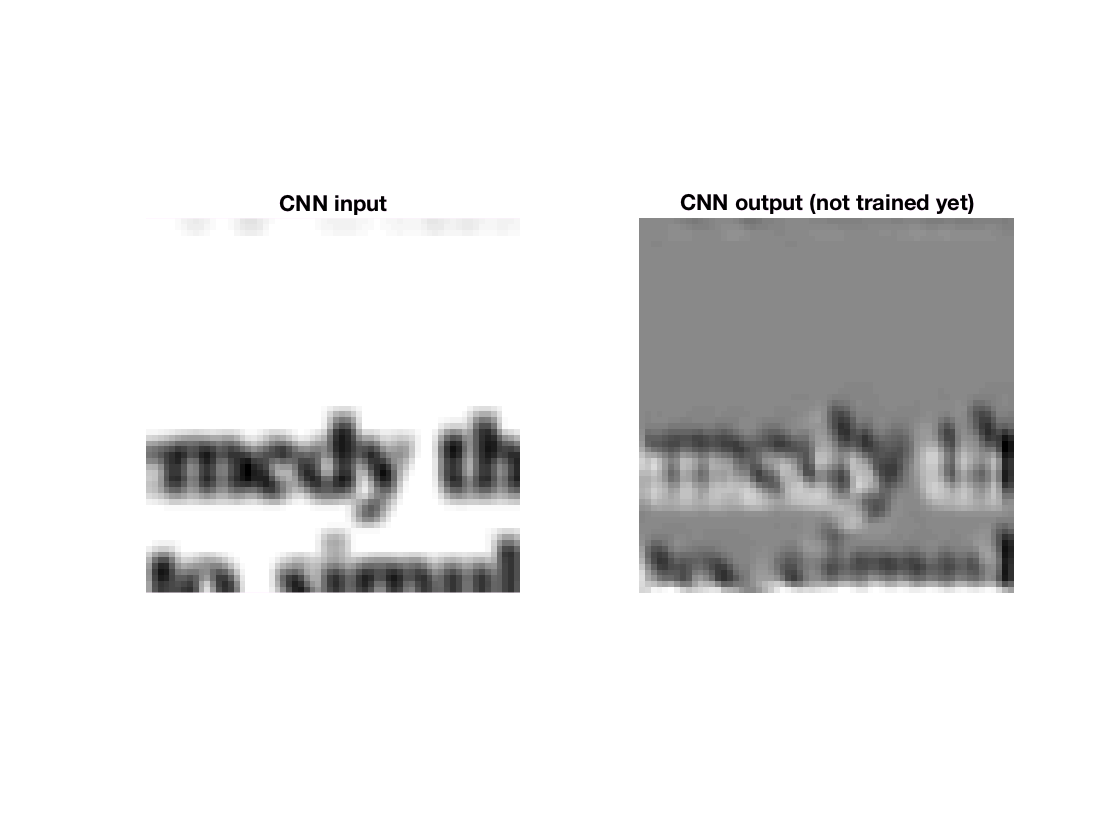


% Evaluate network on an image
res = vl_simplenn(net, imdb.images.data(:,:,:,1)) ;

figure(32) ; clf ; colormap gray ;
set(gcf,'name', 'Part 3.2: network input') ;
subplot(1,2,1) ;
imagesc(res(1).x) ; axis image off  ;
title('CNN input') ;

set(gcf,'name', 'Part 3.2: network output') ;
subplot(1,2,2) ;
imagesc(res(end).x) ; axis image off  ;
title('CNN output (not trained yet)') ;

## Part 3.3: learn the model

% Add a loss (using a custom layer)
tic
net = addCustomLossLayer(net, @l2LossForward, @l2LossBackward) ;

% Extra: uncomment the following line to use your implementation
% of the L1 loss
net = addCustomLossLayer(net, @l1LossForward, @l1LossBackward) ;

% Train
trainOpts.expDir = 'data/text-small' ;
trainOpts.gpus = [] ;
% Uncomment for GPU training:
%trainOpts.expDir = 'data/text-small-gpu' ;
%trainOpts.gpus = [1] ;
trainOpts.batchSize = 1 ;
trainOpts.learningRate = 0.02 ;
trainOpts.plotDiagnostics = false ;
% trainOpts.plotDiagnostics = true ; % Uncomment to plot diagnostics
trainOpts.numEpochs = 20 ;
trainOpts.errorFunction = 'none' ;

Error using timeit (line 34)
Not enough input arguments.


net = cnn_train(net, imdb, @getBatch, trainOpts) ;

% Deploy: remove loss
net.layers(end) = [] ;
toc

## Part 3.4: evaluate the model

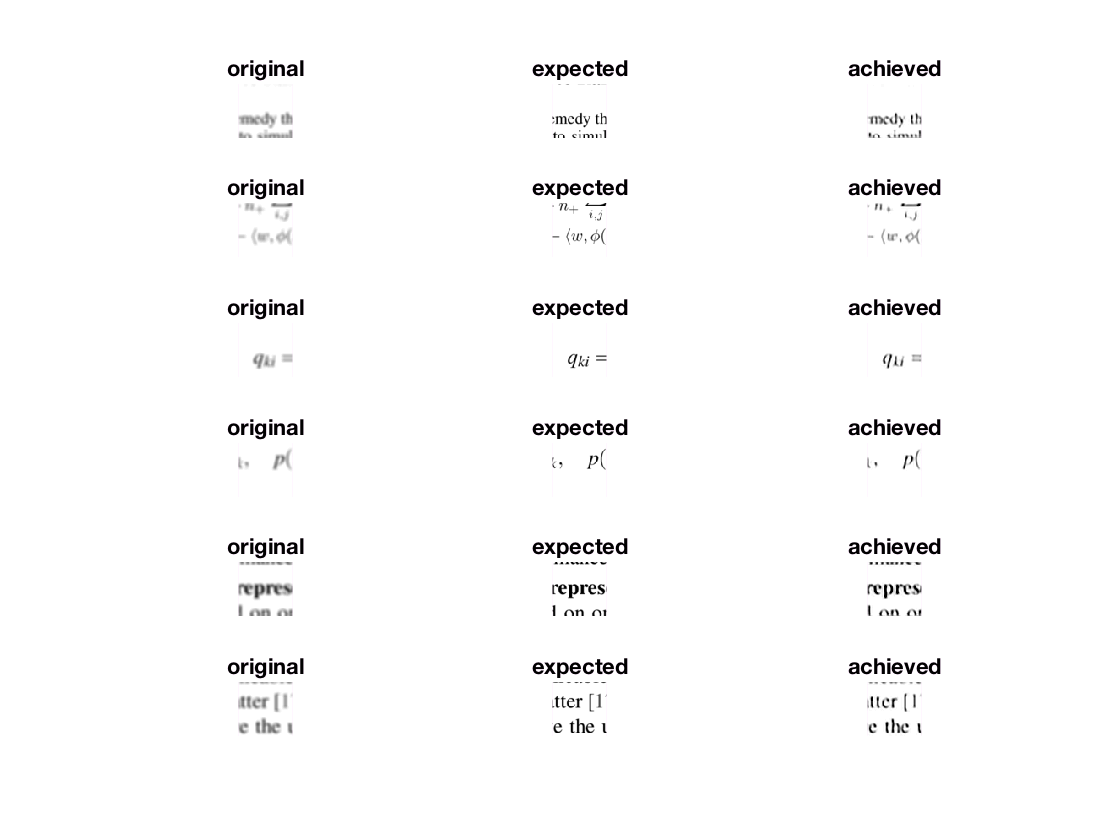

train = find(imdb.images.set == 1) ;
val = find(imdb.images.set == 2) ;

figure(33) ; set(gcf, 'name', 'Part 3.4: Results on the training set') ;
showDeblurringResult(net, imdb, train(1:30:151)) ;

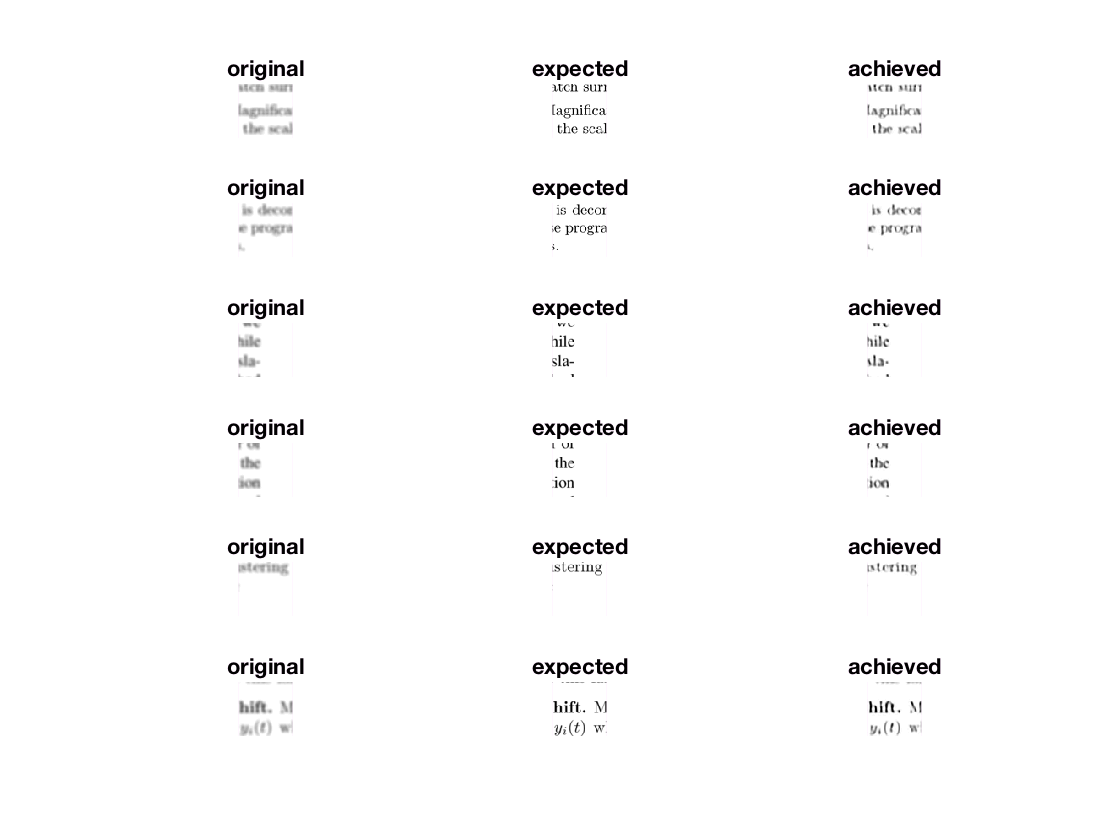


figure(34) ; set(gcf, 'name', 'Part 3.4: Results on the validation set') ;
showDeblurringResult(net, imdb, val(1:30:151)) ;

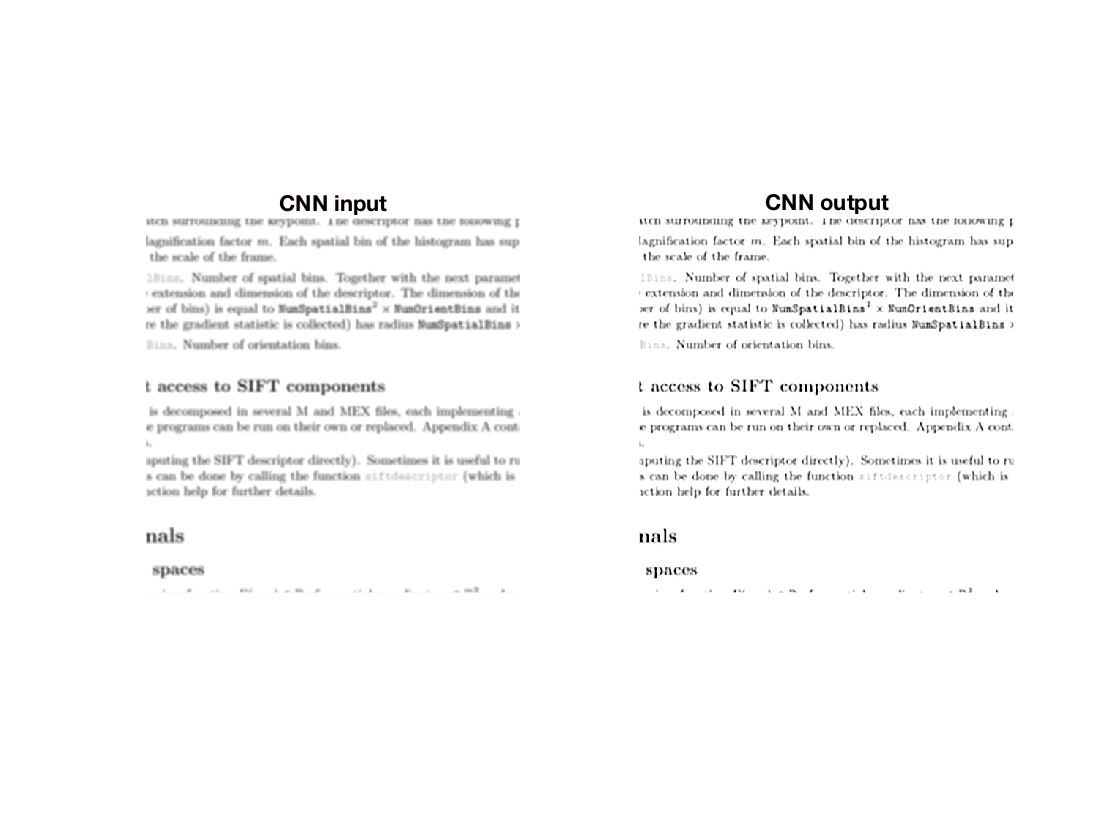


figure(35) ;
set(gcf, 'name', 'Part 3.4: Larger example on the validation set') ;
colormap gray ;
subplot(1,2,1) ; imagesc(imdb.examples.blurred{1}, [-1, 0]) ;
axis image off ;
title('CNN input') ;
res = vl_simplenn(net, imdb.examples.blurred{1}) ;
subplot(1,2,2) ; imagesc(res(end).x, [-1, 0]) ;
axis image off ;
title('CNN output') ;